# Cough-Signal Based COVID Detection Model 

BME 3053C Group Project MATLAB Header and Live Script

Group Members:Jasmine Day, Zinia Basil, Ahmet Bilgili

Course: BME 3053C Computer Applications for BME

Term: Spring 2021

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

April 12, 2021

Description: Our project is based around the variations of signal frequencies in cough recordings between healthy and COVID-19 patients. Recording a cough noise to feed into an algorithm is a cost-effective and efficient method of offering a general wide range use test for potentially infected patients to have some degree of certainty around their health status. We are achieving this through the utilization of decision tree, KNN, and support vector machine to train a model that can be used to predict potential COVID-19 patients based on signal variations of their coughs. 

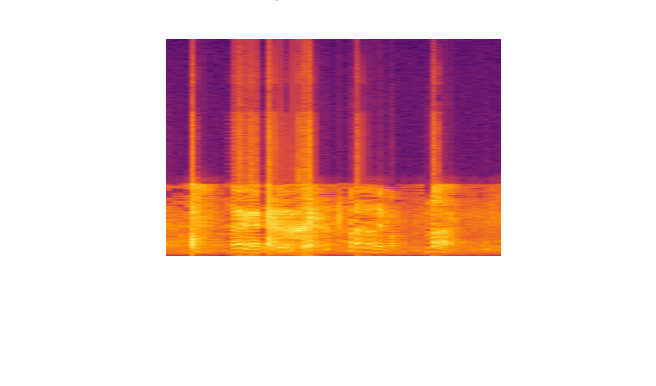

clc;clear;
% load data (old data)
% [train_x, train_y, test_x, test_y, classes] = load_data;
% dataP = [train_x, train_y; test_x, test_y];
% histogram(dataP)
% title('Date Set Distribution')
% visulization of the data 

imshow('_-_5kbw2Mcw_ 0000_ 10000.png')
title("Example Mel Spectograms of one ofthe participants")


% load our data 
load featureData.mat 
ourdata = table2array(data)

ourdata = 	1.0e+03 *

    0.2402    1.4104   -0.0706    0.0042   -0.0018    0.0006    0.0004    0.0007   -0.0008    0.0008   -0.0004    0.0006    0.0004    0.0002   -0.0002    3.4147    0.0000    1.2860    0.0834   -0.0000   -0.0001         0
    0.2254    1.4246   -0.0566    0.0040   -0.0003   -0.0002   -0.0007   -0.0009   -0.0009   -0.0006   -0.0004    0.0000   -0.0001   -0.0001   -0.0002    4.5191    0.0000    1.5205    0.0673   -0.0000    0.0001         0
    0.2703    1.0437   -0.0515    0.0070   -0.0046   -0.0007   -0.0023    0.0002   -0.0019    0.0000   -0.0006   -0.0001    0.0005   -0.0002   -0.0002    1.8313    0.0000    0.5221    0.0919   -0.0000    0.0000         0
    0.2154    1.4104   -0.0524    0.0027   -0.0005   -0.0000   -0.0002    0.0002   -0.0007   -0.0000   -0.0003    0.0005   -0.0002    0.0003   -0.0004    5.9271    0.0000    1.2860    0.0834   -0.0000   -0.0001         0
    0.1627    1.4299   -0.0543    0.0038    0.0004    0.0005    0.0000   -0.0005   -0.0005   -

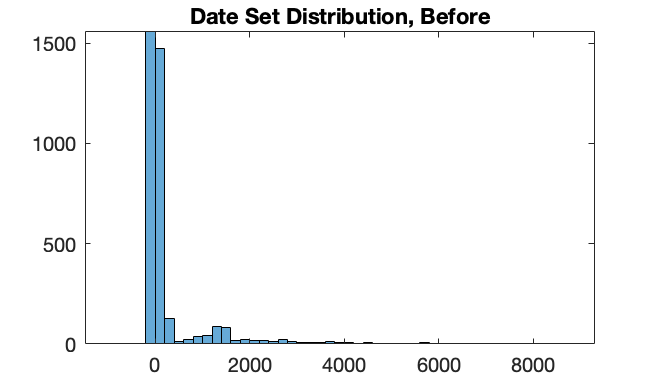

histogram(ourdata)
title('Date Set Distribution, Before') 

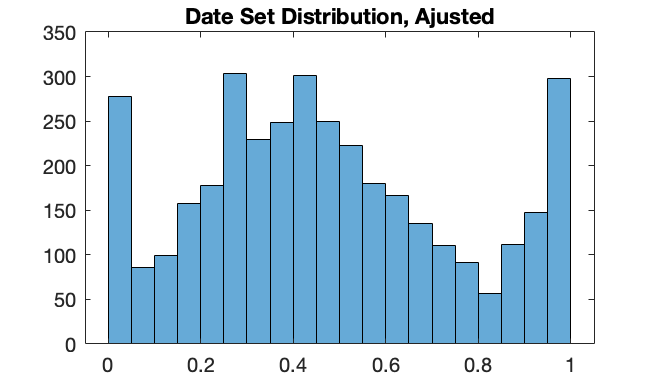

% normalize the data 
for i = 1: size(ourdata,2)-1 
        temp = ourdata(:,i);
        maximum = max(temp);
        minimum = min(temp);
        for j = 1:length(temp)
            temp(j) = (temp(j)-minimum )/(maximum - minimum);
        end 
        ourdata(:,i) = temp; 
end 

histogram(ourdata)
title('Date Set Distribution, Ajusted') 


% Since we will use cross validation on all 3 models. We will use a seed of
% 10 for reproduciblity purposes 
rng(10)

## Decision Tree Model 

% Train the decision tree model using cross validation 
dt = fitctree(ourdata(:,1:size(ourdata,2)-1), ourdata(:,size(ourdata,2)), 'CrossVal','On')

dt =   ClassificationPartitionedModel
    CrossValidatedModel: 'Tree'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'  'x12'  'x13'  'x14'  'x15'  'x16'  'x17'  'x18'  'x19'  'x20'  'x21'}
           ResponseName: 'Y'
        NumObservations: 166
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods



% predict the labels 
dtClass = kfoldPredict(dt)

dtClass =      0
     0
     0
     0
     0
     0
     0
     0
     1
     0



% Compute the kfold loss 
dtResubErr = kfoldLoss(dt)

dtResubErr = 0.0723


% Compute the accuracy of the model 
accuracy = sum(dtClass == ourdata(:,size(ourdata,2)))/length(ourdata(:,size(ourdata,2)))

accuracy = 0.9277


% confusion matrix 
deResubCM = confusionchart(ourdata(:,size(ourdata,2)),dtClass)

deResubCM =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


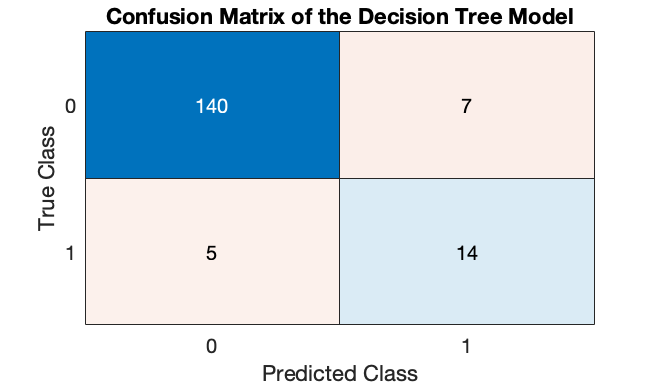

title('Confusion Matrix of the Decision Tree Model');

## KNN Model 

knnmodel = fitcknn(ourdata(:,1:size(ourdata,2)-1),ourdata(:,size(ourdata,2)),'NumNeighbors',5);

CVKnnmodel = crossval(knnmodel,'KFold',5)

CVKnnmodel =   ClassificationPartitionedModel
    CrossValidatedModel: 'KNN'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'  'x12'  'x13'  'x14'  'x15'  'x16'  'x17'  'x18'  'x19'  'x20'  'x21'}
           ResponseName: 'Y'
        NumObservations: 166
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods



kloss = kfoldLoss(CVKnnmodel)

kloss = 0.0422


predictions = kfoldPredict(CVKnnmodel)

predictions =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



accuracy = sum(predictions == ourdata(:,size(ourdata,2)))/length(ourdata(:,size(ourdata,2))) 

accuracy = 0.9578

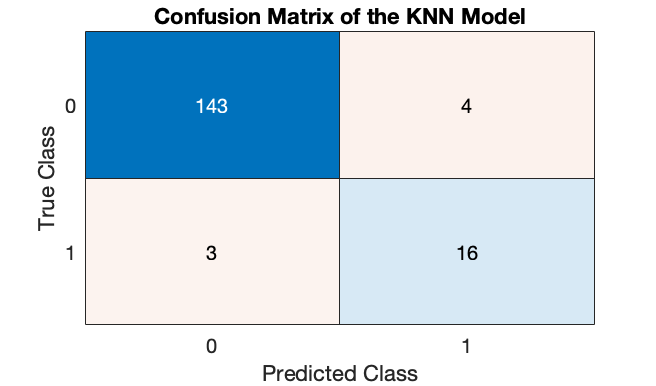


confusionchart(ourdata(:,size(ourdata,2)),predictions)
title('Confusion Matrix of the KNN Model');

## SVM Model 

% Train binary classification model of SVM 
SVMModel = fitcsvm(ourdata(:,1:size(ourdata,2)-1), ourdata(:,size(ourdata,2)))

SVMModel =   ClassificationSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 166
                    Alpha: [36×1 double]
                     Bias: -3.9387
         KernelParameters: [1×1 struct]
           BoxConstraints: [166×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [166×1 logical]
                   Solver: 'SMO'


  Properties, Methods



% Using cross validation 
SVMMdl = crossval(SVMModel)

SVMMdl =   ClassificationPartitionedModel
    CrossValidatedModel: 'SVM'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'  'x12'  'x13'  'x14'  'x15'  'x16'  'x17'  'x18'  'x19'  'x20'  'x21'}
           ResponseName: 'Y'
        NumObservations: 166
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods



% Class labels; 0 represents non-COVID patient and 1 represents COVID
% patient
classOrder = SVMModel.ClassNames 

classOrder =      0
     1



% predicting the label of the test set 
label = kfoldPredict(SVMMdl)

label =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



% calculating the accuracy of the model 
accuracy = sum(label == ourdata(:,size(ourdata,2)))/length(ourdata(:,size(ourdata,2)))

accuracy = 0.9578


% resubstitution error 
svmResuberror = kfoldLoss(SVMMdl)

svmResuberror = 0.0422

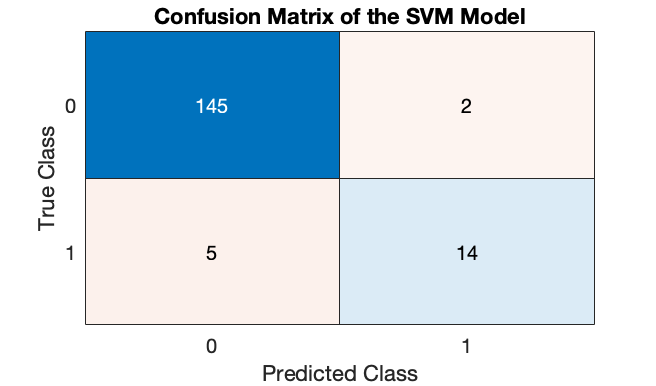


% confusion matrix 
confusionchart(ourdata(:,size(ourdata,2)),label)
title('Confusion Matrix of the SVM Model');

## Summary 

Overall, KNN and SVM have the better performances comapred to Decision Tree Model. All 3 models have higher than 90% accuracy. 